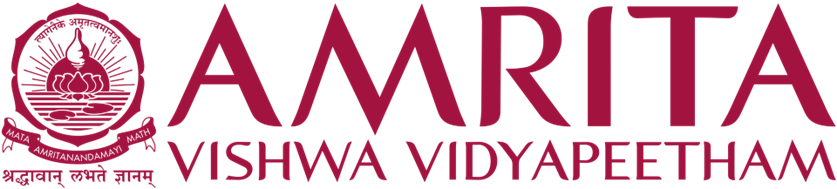

`22MAT230     MATHEMATICS  FOR  COMPUTING 4`

***Batch : AIE -C***

***Team 7***

-------------------------------------------------------------------

**G Prajwal Priyadarshan  -  CB.SC.U4AIE24214**

**Kabilan K               -  CB.SC.U4AIE24224**

**Kishore B                         -  CB.SC.U4AIE24227**

**Rahul L S                          - CB.SC.U4AIE24248**

-------------------------------------------------------------------

# **LLM Guided Regularization of Pseudoinverse for Ill-Posed Signal Reconstruction**

## **Problem Statement**

## **What Are ill Posed Inverse Problems?**

A problem Ax = b is WELL POSED if:

1) Solution exists

2) Solution is unique

3) Solution depends continuously on data

We study conditioning using singular values and condition number.

## Well Posed vs ill Posed Problems

### Example

1) Full Rank Matrix

clc, clearvars
n = 100;
A1 = randn(n);              % Random Full rank matrix

[U1, S1, V1] = svd(A1);
singular_vals_A1 = diag(S1);

% Condition number
cond_A1 = cond(A1);
disp('Condtion number of Well Posed Matrix')

Condtion number of Well Posed Matrix


disp(cond_A1)

  163.9431



2) ill Posed Matrix

function A = rankdeficient_operator(n, r)
    [U,~,V] = svd(randn(n), 'econ');   % random orthogonal matrices
    s = [linspace(1,0.1,r) zeros(1,n-r)];   % r non-zero singular values
    A = U * diag(s) * V';   % construct matrix
end
A2 = rank_deficient_operator(n, 12);
[U2, S2, V2] = svd(A2);
singular_vals_A2 = diag(S2);

% Condition number
cond_A2 = cond(A2);

disp('Condition number of Ill posed Matrix:')

Condition number of Ill posed Matrix:


disp(cond_A2)

   2.7094e+18



### Singular Value Spectrum

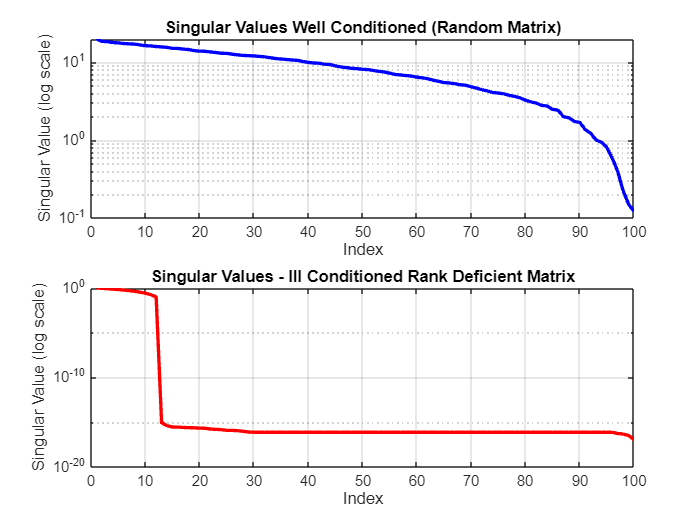

figure;
subplot(2,1,1)
semilogy(singular_vals_A1, 'b', 'LineWidth', 2);
grid on;
title('Singular Values Well Conditioned (Random Matrix)');
xlabel('Index');
ylabel('Singular Value (log scale)');

subplot(2,1,2)
semilogy(singular_vals_A2, 'r', 'LineWidth', 2);
grid on;
title('Singular Values - Ill Conditioned Rank Deficient Matrix');
xlabel('Index');
ylabel('Singular Value (log scale)');

### Stability Check

b1 = randn(n,1);
b1_noisy = b1 + 1e-6*randn(n,1);

x1_original = A1 \ b1;
x1_noisy    = A1 \ b1_noisy;
difference_well = norm(x1_original - x1_noisy);

x2_original = A2 \ b1;

x2_noisy    = A2 \ b1_noisy;

difference_ill = norm(x2_original - x2_noisy);

disp('Difference for Well-Conditioned Matrix:')

Difference for Well-Conditioned Matrix:


disp(difference_well)

   9.4879e-06




disp('Difference for Ill-Conditioned Matrix:')

Difference for Ill-Conditioned Matrix:


disp(difference_ill)

   1.3025e+14



### Condition Number via Singular Value

cond_manual_A1 = max(singular_vals_A1) / min(singular_vals_A1);
cond_manual_A2 = max(singular_vals_A2) / min(singular_vals_A2);

disp('Manual Condition Number (Random):')

Manual Condition Number (Random):


disp(cond_manual_A1)

  163.9431





disp('Manual Condition Number (Hilbert):')

Manual Condition Number (Hilbert):


disp(cond_manual_A2)

   9.0129e+16



## Methodology

This study investigates inverse problem behavior under different numerical conditions. First, **synthetic signals** are generated to create controlled experimental data. A **forward model** is applied to simulate the measurement process, and **noise models** are introduced to represent real-world uncertainties. The **condition number** of the system matrix is analyzed to identify well-conditioned and ill-conditioned cases. Different **reconstruction methods** are then used to recover the original signal from noisy observations, and their performance is evaluated using suitable **evaluation metrics**.

### Signal Generation

function y = sinusoid(t)
    y = sin(2*pi*t) + 0.5*sin(6*pi*t);
end

function y = multisine(t, freqs, amps)
    if nargin < 2
        freqs = [2 5 9];
    end
    if nargin < 3
        amps = [1.0 0.6 0.3];
    end

    y = zeros(size(t));
    for k = 1:length(freqs)
        y = y + amps(k) * sin(2*pi*freqs(k)*t);
    end
end

function y = piecewise_signal(t)
    y = zeros(size(t));
    N = length(t);
    thirds = floor(N/3);

    y(1:thirds) = 1.0;
    y(thirds+1:2*thirds) = -0.5;
    y(2*thirds+1:end) = 0.7;
end

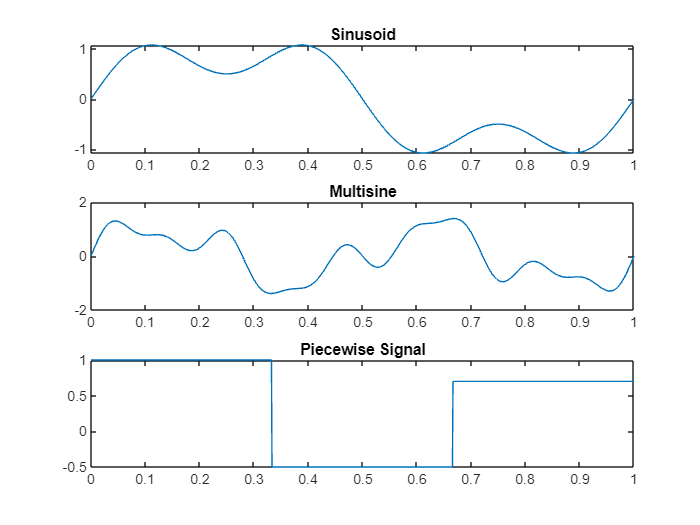

t = linspace(0, 1, 1000);

y1 = sinusoid(t);
y2 = multisine(t);
y3 = piecewise_signal(t);

figure;
subplot(3,1,1); plot(t, y1); title('Sinusoid');
subplot(3,1,2); plot(t, y2); title('Multisine');
subplot(3,1,3); plot(t, y3); title('Piecewise Signal');

### Forward Models

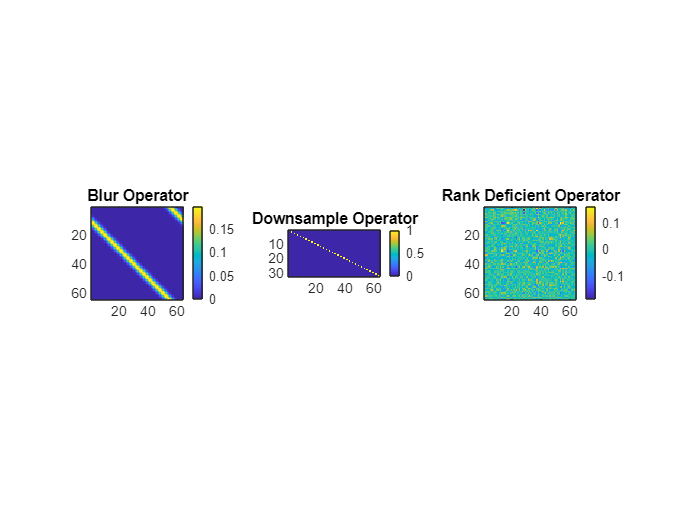

n = 64;

A_blur = blur_operator(n, 2.0);
A_down = downsample_operator(n, 2);
A_rank = rankdeficient_operator(n, 12);

figure;
subplot(1,3,1); imagesc(A_blur); axis image;
title('Blur Operator'); colorbar;

subplot(1,3,2); imagesc(A_down); axis image;
title('Downsample Operator'); colorbar;

subplot(1,3,3); imagesc(A_rank); axis image;
title('Rank Deficient Operator'); colorbar;

function A = blur_operator(n, sigma, kernel_radius)
% BLUR_OPERATOR  Circulant Gaussian blur matrix

    if nargin < 3
        kernel_radius = 10;
    end

    ksize = 2 * kernel_radius + 1;
    k = gaussian_kernel(ksize, sigma);

    A = zeros(n, n);

    for i = 1:n
        for j = 1:n
            shift = mod(i - j, n);
            if shift < ksize
                A(i, j) = k(shift + 1);
            end
        end
    end
end

function A = downsample_operator(n, factor)
% DOWNSAMPLE_OPERATOR  Downsampling matrix

    if nargin < 2
        factor = 2;
    end

    m = floor(n / factor);
    A = zeros(m, n);

    for i = 1:m
        A(i, (i-1)*factor + 1) = 1.0;
    end
end

function A = rank_deficient_operator(n, r)
    [U,~,V] = svd(randn(n), 'econ');   % random orthogonal matrices
    s = [linspace(1,0.1,r) zeros(1,n-r)];   % r non-zero singular values
    A = U * diag(s) * V';   % construct matrix
end

function k = gaussian_kernel(sz, sigma)
% GAUSSIAN_KERNEL  1D Gaussian kernel

    idx = -(floor(sz/2)) : floor(sz/2);
    k = exp(-0.5 * (idx / sigma).^2);
    k = k / sum(k);
end

### Noise Models

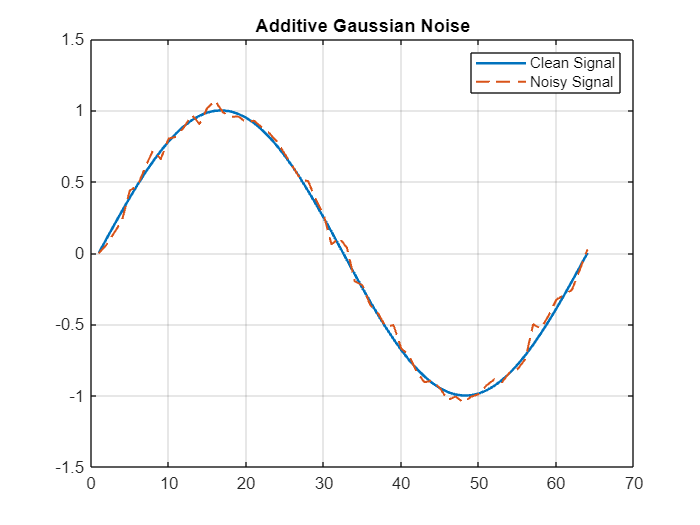

n = 64;
t = linspace(0, 1, n)';
x = sin(2*pi*t);

sigma = 0.05;

[y_noisy, noise] = add_gaussian_noise(x, sigma);

figure;
plot(x, 'LineWidth', 1.5); hold on;
plot(y_noisy, '--', 'LineWidth', 1.2);
legend('Clean Signal', 'Noisy Signal');
title('Additive Gaussian Noise');
grid on;

function [y_noisy, noise] = add_gaussian_noise(y, sigma, rng)
    if nargin < 3 || isempty(rng)
        noise = sigma * randn(size(y));
    else
        noise = sigma * randn(rng, size(y));
    end

    y_noisy = y + noise;
end

### Reconstruction Methods

### Evaluation Metrics